R_t = R25 * e^b(1/T - 1/298.15)

[https://electronics.stackexchange.com/questions/648571/what-is-thermistor-beta](https://electronics.stackexchange.com/questions/648571/what-is-thermistor-beta)

T = 1/(ln(R_t / R25)/b+1/298.15)

V_t = R_t/(10000 + R_t) * 5

5/V_t  * R_t = 10000 + Rt

(5/V_t  - 1) R_t = 10000

R_t = 10000/(5/V_t  - 1)

b = 3950

R25 = 10000

P = (12*D)^2 * 8.8

block dimensions: 2" x 2+3/8" x 0.5"

l = 2/39.37 %convert quantities to m

l = 0.0508

w = (2+3/8)/39.37

w = 0.0603

h = 0.5/39.37

h = 0.0127

A_air = l*w + l*h*2 + w*h*2

A_air = 0.0059

h_air = 15 %W/m^2*K

h_air = 15

T_f = 25 %assume room temp

T_f = 25

convection heat transfer coefficent of air 15 W/m^2*K (approx.)

https://www.engineersedge.com/heat_transfer/convective_heat_transfer_coefficients__13378.htm

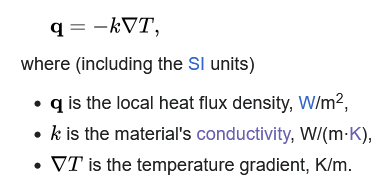

Assuming uniform heat flux density

Multiply by area to get watts

Gradient of T is just pad temp - block temp

conductive heat transfer coefficient of aluminum = 164 W/m*K

https://www.engineeringtoolbox.com/thermal-conductivity-metals-d_858.html

A_pad = l*w

A_pad = 0.0031

k = 164

k = 164

Open loop system:

duty cycle -> Q pad

We can control Q pad

| Q pad = k(T_pad - T_block) * A_pad

| Q_pad/(k*A_pad) = T_pad - T_block

| Q_air = h*A_air(T_block - 25)

Q_pad - Q_air = Q_aluminum

integral of Q_aluminum (watts) is J_aluminum (joules) (so Q_alluminum/s = J_aluminum)

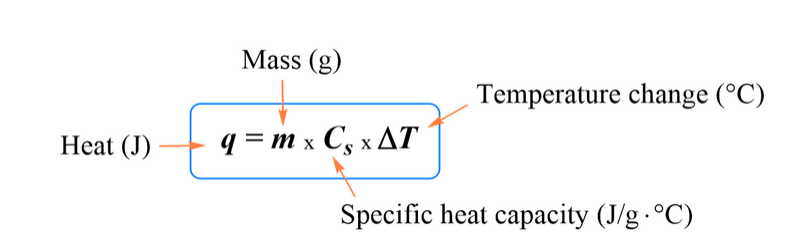

Specific heat of aluminum is 0.90 J/g ° C https://web.fscj.edu/Milczanowski/psc/lect/Ch4/slide5.htm

delta t is T_requested - T_block

mass of aluminum block is 100g

m = 100 %g

m = 100

Cs = 0.90 % J/g ° C

Cs = 0.9000

therefore

T_requested - T_block ->

m*Cs*(T_requested - T_block) = J_aluminum ->

J_aluminum * S = Q_aluminum ->

Q_aluminum - Q_air = Q_pad ->

We control Q_pad!

Q_pad =  (12*D)^2 * 8.8

sqrt(Q_pad/8.8)/12 * 100= D 

Conduction of pad to ground (wood block)

Conductive heat transfer coefficent of wood 0.10 W/m K

[http://hyperphysics.phy-astr.gsu.edu/hbase/Tables/thrcn.html](http://hyperphysics.phy-astr.gsu.edu/hbase/Tables/thrcn.html)

Since aluminum >> wood, can neglect (or model if we really want to)

A_pad * 0.1 * (30-25)

ans = 0.0015